**MATLAB/Simulink Session 2**

**Part 2**

**Symbolic Laplace Calculation**

% laplace with syms
syms t s 
laplace(cos(t))

$$ans = \frac{s}{s^{2}+1}$$

laplace(sin(t))

$$ans = \frac{1}{s^{2}+1}$$

y = t*exp(-t)

$$y = t\,{\mathrm{e}}^{-t}$$

laplace(y)

$$ans = \frac{1}{{\left(s+1\right)}^{2}}$$

syms y(t) a
eqn = diff(y,t) == a*y;
y = dsolve(eqn)

$$y = C_{1}\,{\mathrm{e}}^{a\,t}$$

laplace(y)

$$ans = -\frac{C_{1}}{a-s}$$

**Laplace Inverse Calculation**

% inverse laplace
ilaplace(ans)

$$ans = C_{1}\,{\mathrm{e}}^{a\,t}$$

syms t s
G = 1/(s + 1)

$$G = \frac{1}{s+1}$$

ilaplace(G)

$$ans = {\mathrm{e}}^{-t}$$

**Define Laplase: Seccond Method**

**Note: To plot the step response or calculate DC gain, poles and zeros, use methods below.**

% another method
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = 1/(s + 1)

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



clc;
clear

% 1st method
N = [1 1]

N =      1     1


D = [1 2 1]

D =      1     2     1


G1 = tf(N, D)

G1 =
 
      s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



% 2nd method
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G2 = (s+1)/(s^2 + 2*s + 1)

G2 =
 
      s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



**Poles, Zeros and DC gain of Transfer Functions**

% poles, zeros, dc gain
zero(G2)

ans = -1

pole(G2)

ans =     -1
    -1


dcgain(G2)

ans = 1

**Step Response**

% step response
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G1 = 1/(s+1)

G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



G2 = 1/(s+1)^2

G2 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



G3 = 1/(s+1)^3

G3 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



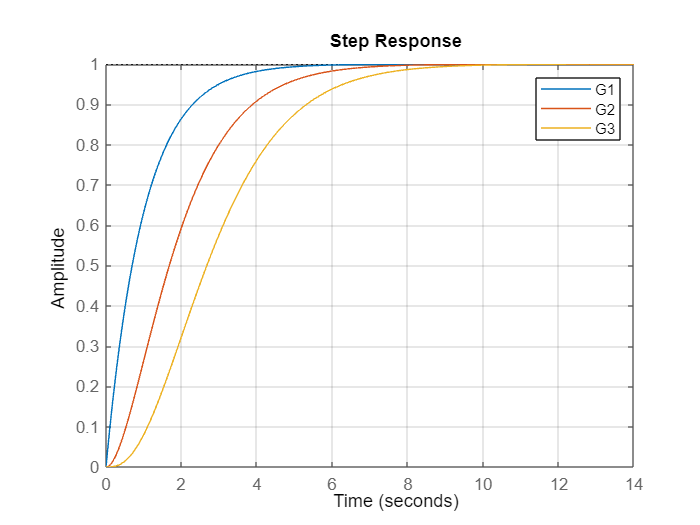

step(G1)
hold on
step(G2)
step(G3)
grid on
legend

clc
close all
clear
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



H1 = (s+1)/(s+2)

H1 =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.



H2 = 2/(s+2)

H2 =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.



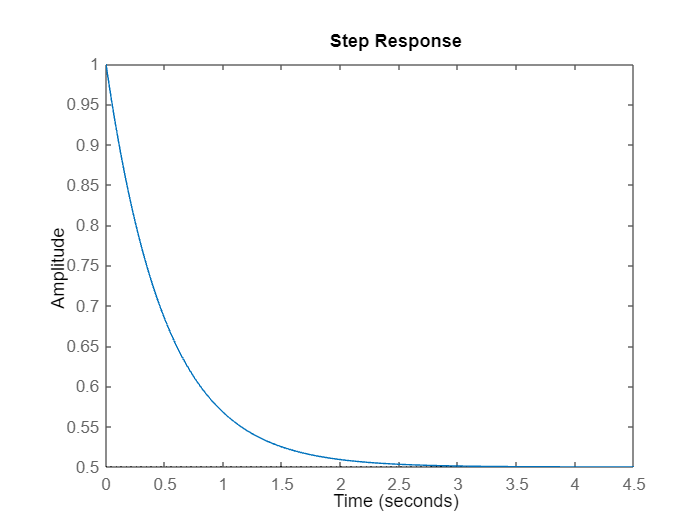


step(H1)

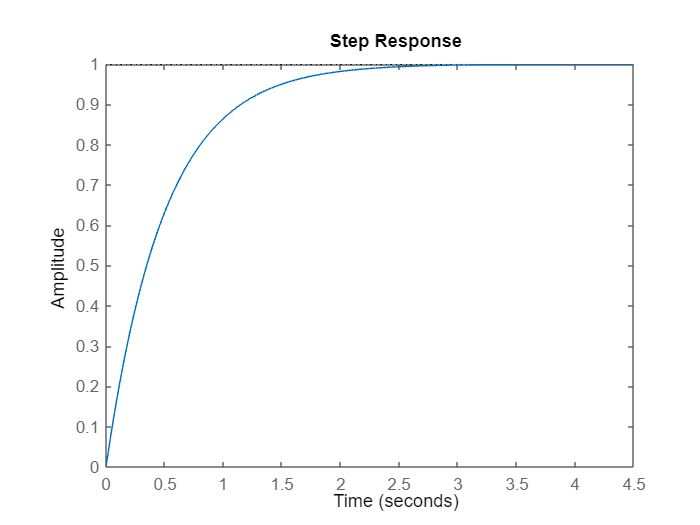

step(H2)